load pClouds.mat

maxLidarRange = 20;
referenceVector = [0 0 1];
maxDistance = 0.5;
maxAngularDistance = 15;

randomSampleRatio = 0.25;
gridStep = 2.5;
distanceMovedThreshold = 0.3;

loopClosureSearchRadius = 3;

nScansPerSubmap = 3;
subMapThresh = 50;

annularRegionLimits = [-0.75 0.75];

rmseThreshold = 0.26;

loopClosureThreshold = 150;
optimizationInterval = 2;


% 3D Posegraph object for storing estimated relative poses
pGraph = poseGraph3D;
% Default serialized upper-right triangle of 6-by-6 Information Matrix
infoMat = [1,0,0,0,0,0,1,0,0,0,0,1,0,0,0,1,0,0,1,0,1];
% Number of loop closure edges added since last pose graph optimization and map refinement
numLoopClosuresSinceLastOptimization = 0; 
% True after pose graph optimization until the next scan
mapUpdated = false;
% Equals to 1 if the scan is accepted
scanAccepted = 0;

% 3D Occupancy grid object for creating and visualizing 3D map
mapResolution = 8; % cells per meter
omap = occupancyMap3D(mapResolution);

pcProcessed = cell(1,length(pClouds));
lidarScans2d = cell(1,length(pClouds)); 
submaps = cell(1,length(pClouds)/nScansPerSubmap);

pcsToView = cell(1,length(pClouds)); 

% Set to 1 to visualize created map and posegraph during build process
viewMap = 1; 
% Set to 1 to visualize processed point clouds during build process
viewPC = 0;

%set random seed to guarantee consistent random sampling
rng(0);

% If you want to view the point clouds while processing them sequentially
if viewPC==1
    pplayer = pcplayer([-50 50],[-50 50],[-10 10],'MarkerSize',10);
end

% If you want to view the created map and posegraph during build process
if viewMap==1
    ax = newplot; % Figure axis handle
    view(20,50);
    grid on;
end


count = 0; % Counter to track number of scans added
disp('Estimating robot trajectory...');

Estimating robot trajectory...


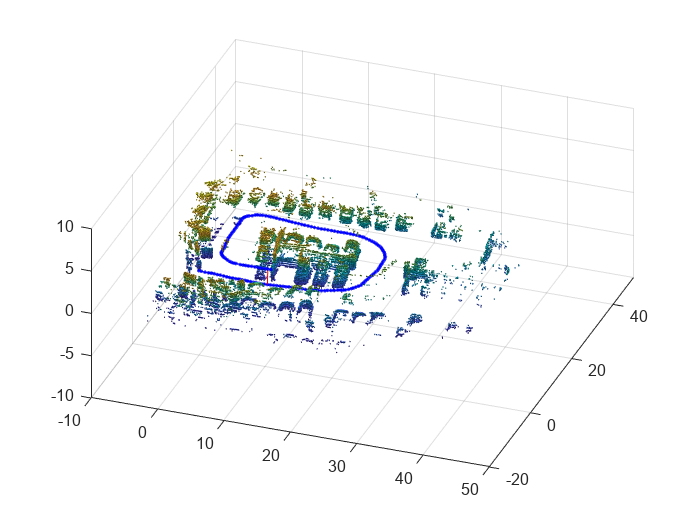

Doing Pose Graph Optimization to reduce drift.


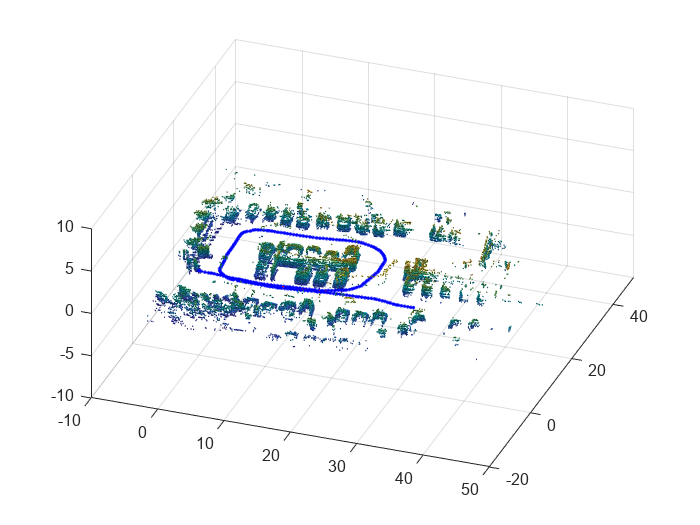


for i=1:length(pClouds)
    % Read point clouds in sequence
    pc = pClouds{i};




   ind = (-maxLidarRange < pc(:,1) & pc(:,1) < maxLidarRange ...
        & -maxLidarRange  < pc(:,2) & pc(:,2) < maxLidarRange ...
        & (abs(pc(:,2))>abs(0.5*pc(:,1)) | pc(:,1)>0));
    
    pcl = pointCloud(pc(ind,:));

    [~, ~, outliers] = ...
        pcfitplane(pcl, maxDistance,referenceVector,maxAngularDistance);
    pcl_wogrd = select(pcl,outliers,'OutputSize','full');

    [~, ~, outliers] = ...
        pcfitplane(pcl_wogrd,0.2,referenceVector,maxAngularDistance);
    pcl_wogrd = select(pcl_wogrd,outliers,'OutputSize','full');

    ind = (pcl_wogrd.Location(:,3)<annularRegionLimits(2))&(pcl_wogrd.Location(:,3)>annularRegionLimits(1));
    pcl_wogrd = select(pcl_wogrd,ind,'OutputSize','full');

    pcl_wogrd_sampled = pcdownsample(pcl_wogrd,'random',randomSampleRatio);
    
    if viewPC==1
        % Visualize down sampled point cloud
        view(pplayer,pcl_wogrd_sampled);
        pause(0.001)
    end




    if count == 0
        % First can
        tform = [];
        scanAccepted = 1;
    else
        if count == 1
            tform = pcregisterndt(pcl_wogrd_sampled,prevPc,gridStep);
        else
            tform = pcregisterndt(pcl_wogrd_sampled,prevPc,gridStep,...
                'InitialTransform',prevTform);
        end
        
        relPose = [tform2trvec(tform.T') tform2quat(tform.T')];
        
        if sqrt(norm(relPose(1:3))) > distanceMovedThreshold
            addRelativePose(pGraph,relPose);
            scanAccepted = 1;
        else
            scanAccepted = 0;
        end
    end
    


    if scanAccepted == 1
        count = count + 1;
        
        pcProcessed{count} = pcl_wogrd_sampled;
        
        lidarScans2d{count} = exampleHelperCreate2DScan(pcl_wogrd_sampled);
        
        % Submaps are created for faster loop closure query. 
        if rem(count,nScansPerSubmap)==0
            submaps{count/nScansPerSubmap} = exampleHelperCreateSubmap(lidarScans2d,...
                pGraph,count,nScansPerSubmap,maxLidarRange);
        end
        
        % loopSubmapIds contains matching submap ids if any otherwise empty.   
        if (floor(count/nScansPerSubmap)>subMapThresh)
            [loopSubmapIds,~] = exampleHelperEstimateLoopCandidates(pGraph,...
                count,submaps,lidarScans2d{count},nScansPerSubmap,...
                loopClosureSearchRadius,loopClosureThreshold,subMapThresh);
            
            if ~isempty(loopSubmapIds)
                rmseMin = inf;
                
                % Estimate best match to the current scan
                for k = 1:length(loopSubmapIds)
                    % For every scan within the submap
                    for j = 1:nScansPerSubmap
                        probableLoopCandidate = ...
                            loopSubmapIds(k)*nScansPerSubmap - j + 1;
                        [loopTform,~,rmse] = pcregisterndt(pcl_wogrd_sampled,...
                            pcProcessed{probableLoopCandidate},gridStep);
                        % Update best Loop Closure Candidate
                        if rmse < rmseMin
                            loopCandidate = probableLoopCandidate;
                            rmseMin = rmse;
                        end
                        if rmseMin < rmseThreshold
                            break;
                        end
                    end
                end
                
                % Check if loop candidate is valid
                if rmseMin < rmseThreshold
                    % loop closure constraint
                    relPose = [tform2trvec(loopTform.T') tform2quat(loopTform.T')];
                    
                    addRelativePose(pGraph,relPose,infoMat,...
                        loopCandidate,count);
                    numLoopClosuresSinceLastOptimization = numLoopClosuresSinceLastOptimization + 1;
                end
                     
            end
        end


        if (numLoopClosuresSinceLastOptimization == optimizationInterval)||...
                ((numLoopClosuresSinceLastOptimization>0)&&(i==length(pClouds)))
            if loopClosureSearchRadius ~=1
                disp('Doing Pose Graph Optimization to reduce drift.');
            end
            % pose graph optimization
            pGraph = optimizePoseGraph(pGraph);
            loopClosureSearchRadius = 1;
            if viewMap == 1
                position = pGraph.nodes;
                % Rebuild map after pose graph optimization
                omap = occupancyMap3D(mapResolution);
                for n = 1:(pGraph.NumNodes-1)
                    insertPointCloud(omap,position(n,:),pcsToView{n}.removeInvalidPoints,maxLidarRange);
                end
                mapUpdated = true;
                ax = newplot;
                grid on;
            end
            numLoopClosuresSinceLastOptimization = 0;
            % Reduce the frequency of optimization after optimizing
            % the trajectory
            optimizationInterval = optimizationInterval*7;
        end

        pcToView = pcdownsample(pcl_wogrd_sampled, 'random', 0.5);
        pcsToView{count} = pcToView;
        
        if viewMap==1
            % Insert point cloud to the occupance map in the right position
            position = pGraph.nodes(count);
            insertPointCloud(omap,position,pcToView.removeInvalidPoints,maxLidarRange);
            
            if (rem(count-1,15)==0)||mapUpdated
                exampleHelperVisualizeMapAndPoseGraph(omap, pGraph, ax);
            end
            mapUpdated = false;
        else
            % Give feedback to know that example is running
            if (rem(count-1,15)==0)
                fprintf('.');
            end
        end

         prevPc = pcl_wogrd_sampled;
        prevTform = tform;
    end
end






if (viewMap ~= 1)||(numLoopClosuresSinceLastOptimization>0)
    nodesPositions = nodes(pGraph);
    % Create 3D Occupancy grid
    omapToView = occupancyMap3D(mapResolution);
    
    for i = 1:(size(nodesPositions,1)-1)
        pc = pcsToView{i};
        position = nodesPositions(i,:);
        
        % Insert point cloud to the occupance map in the right position
        insertPointCloud(omapToView,position,pc.removeInvalidPoints,maxLidarRange);
    end
    
    figure;
    axisFinal = newplot;
    exampleHelperVisualizeMapAndPoseGraph(omapToView, pGraph, axisFinal);
end